clear all
close all

# **MOR practical**** session**

# **Session ****2: solving**** the unsteady** **heat** **equation** **with**** PGD (****a-priori****)**

**Eren Alagoz, adapted from Victor Matray's training sessions**

## This notebook provides a general framework for TP2. You are free to use your own code and notations if you wish. 

## It is essential to fully understand what you plan to program before you begin coding, so take the time to work out and formalize your equations on a draft first.

## 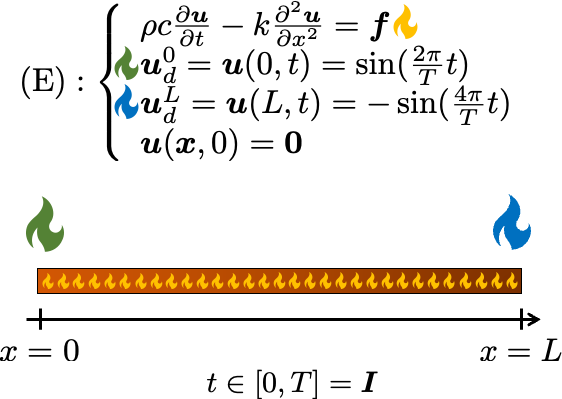

## Physical parameters 

rho = 1 ;
c = 1 ;
k = 1 ;

## Spatial and temporal discretizations

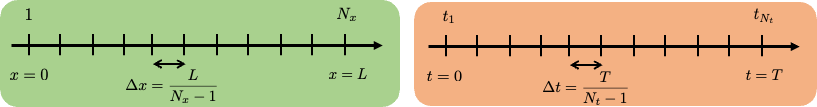

% Domains size
L = 1; % spatial
T = 2; % temporal

% Number of elements
n_X = 300;
n_T = 100;

% Elements size
dx = L / (n_X-1);  
dt = T / (n_T-1);

% List with elements
lx = 0:dx:L;
lt = 0:dt:T;

## Boundary conditions and generalized loading

% TO DO!

Ud0 = sin(2*pi*lt/T); % Boundary conditions on the left
UdL = -sin(4*pi*lt/T); % Boundary conditions on the right

% Volume loading
f = rand(n_X, n_T); 

## Operator construction 

### For calculating integrals (L2 norm) in space and time

% TO DO!

%direct
% Space
I_x = (dx/6) * (2*diag(ones(n_X,1)) + diag(ones(n_X-1,1),1) + diag(ones(n_X-1,1),-1));
% Time
I_t = (dt/6) * (2*diag(ones(n_T,1)) + diag(ones(n_T-1,1),1) + diag(ones(n_T-1,1),-1));

%boucle
Ix = zeros(n_X);
It = zeros(n_T);
Ie_x = dx * [1/3 , 1/6 ; 1/6 , 1/3];
Ie_t = dt * [1/3 , 1/6 ; 1/6 , 1/3];
for i = 1:(n_X - 1)
    Ix(i:i+1 , i:i+1) = Ix(i:i+1 , i:i+1) + Ie_x;
end
for i = 1:(n_T - 1)
    It(i:i+1 , i:i+1) = It(i:i+1 , i:i+1) + Ie_t;
end

### Finite element operator $\mathbb{M} \quad \&  \quad \mathbb{K}  \quad \&  \quad  \underline{\underline{F}}$

% TO DO!

% Mass matrix
M = rho*c * Ix;

% Stiffness matrix
K = (k/dx) * (2*diag(ones(n_X,1)) - diag(ones(n_X-1,1),1) - diag(ones(n_X-1,1),-1));

% Right-hand-side (loading vector)
F = Ix * f;

## Reference solution: Finite Element solution  + BC by substitution + retrograde Euler scheme (implicit) :

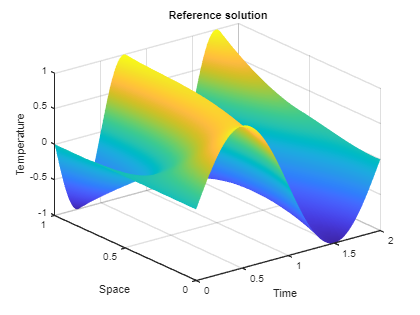

% index of all degrees of freedom (dofs)
dof = 1:n_X;

% index of ddld : blocked dofs
ddld = [1, n_X]; 

% index of ddlu : free dofs
ddlu = setdiff(dof, ddld);
% operator H
H = M/dt + K;  

% Initial condition
Uex = zeros(n_X, n_T);

% Boundary conditions : taken into account with substitution method
Uex(1, :)   = Ud0;            % left BC
Uex(n_X, :) = UdL;            % right BC

% Loop over time steps of Uex for Euler integration
% TO DO !
for i = 2:n_T
    G_rhs = F(:,i) + (M/dt)*Uex(:,i-1);
    Uex(ddlu,i) = H(ddlu,ddlu) \ (G_rhs(ddlu) - H(ddlu,ddld)*Uex(ddld,i));
end

% Plot the reference solution in the time-space domain
figure(1)
surf(lt, lx, Uex)
shading interp
xlabel('Time')
ylabel('Space')
zlabel('Temperature')
title('Reference solution')
shading interp

## Solution with change of variables 

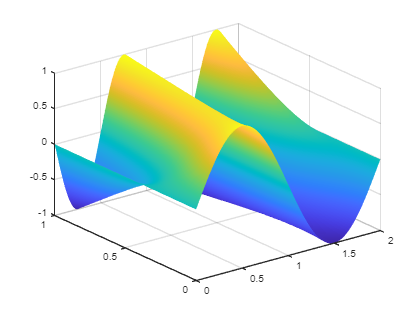

% TO DO !

% Interpolation of the boundary conditions
u_cl = (1 - lx'/L) * Ud0 + (lx'/L) * UdL;

surf(lt, lx, u_cl)
shading interp

### Operator: $\mathbb{D}_t$

% TO DO !

Dt = (1/dt) * (eye(n_T) + diag(-ones(n_T - 1, 1), 1));

u_cl_dot = u_cl * Dt; % Derivative u_cl

### Resolution:

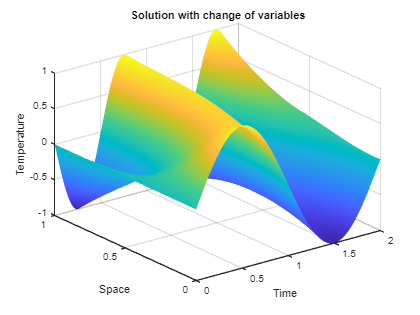

% Right-hand side with the interpolated solution verifying the boundary conditions

% TO DO !
G0 = F - M * u_cl_dot - K * u_cl;

% Initialization of W 
W = zeros(n_X, n_T);

% Loop over time steps of W for Euler integration
for i = 2:n_T
    Gu = G0(ddlu, i);
    ju = Gu + (1/dt) * M(ddlu, ddlu) * W(ddlu, i-1);
    W(ddlu, i) = H(ddlu, ddlu) \ ju;
end

% Solution of the original equation
U1 = W + u_cl; 

% Plot the solution with the change of variable in the time-space domain
figure(2)
surf(lt, lx, U1)
shading interp
xlabel('Time')
ylabel('Space')
zlabel('Temperature')
title('Solution with change of variables')
shading interp

### *Don't forget to compare solution fields and estimate errors!*

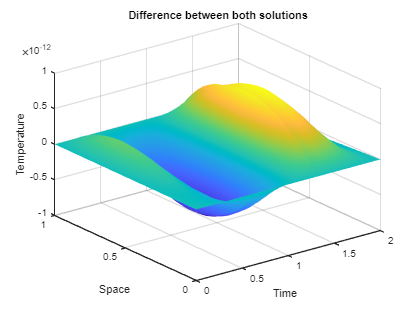

% is_close = all(abs(norm(Uex) - norm(U1)) <= 1e-5, 'all') ;
% disp(is_close)

% Difference Uex - U1
deltaU = (Uex - U1);
figure(3)
surf(lt, lx, deltaU)
shading interp
xlabel('Time')
ylabel('Space')
zlabel('Temperature')
title('Difference between both solutions')
shading interp

## Resolution by PGD

**We look for a decomposition of **$\mathbf{W}$:

### PGD parameters

n_modes = 100; % TO CHANGE
valstagn = 1e-5;

## Initialization

### **Modes storage**

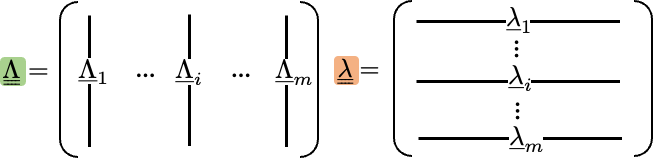      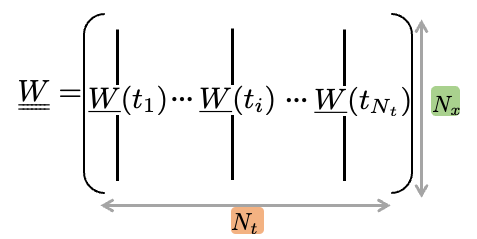

### **Initial right-hand-side**

#### 
$$
    \underline{Q}_0(t) = \underline{F}(t) - \mathbb{M}\dot{\underline{U}}_{CL} - \mathbb{K}\underline{U}_{CL}
$$


% TO DO!
Q0 = F - M * u_cl_dot - K * u_cl; 

LAMBDA = [];        % SPACE modes
lambda = [];        % TIME modes
W = zeros(n_X, n_T);  % PGD field

pgd_errors = [];

## Greedy PGD without update (only fixed point)

### *Problem to solve*

#### 
$$    \forall v \in \mathcal{U}_0, \int_I v^T (\mathbb{M}\dot{\lambda}{\underline{\Lambda}+\mathbb{K}\lambda{\underline{\Lambda}-\underline{Q}(t))dt$$


#### 
$$    \text{with } \underline{Q}(t) = \underline{F}(t) - \mathbb{M}
    \dot{\underline{U}}_{CL}
    - \mathbb{M}
    \sum_{i=1}^{n-1}\dot{\lambda_i}{\underline{\Lambda}_i}
    - \mathbb{K}\underline{U}_{CL} 
    - \mathbb{K}
    \sum_{i=1}^{n-1}\lambda_i{\underline{\Lambda}_i}$$


### *Fixed-point equivalent to sequently solve :*

              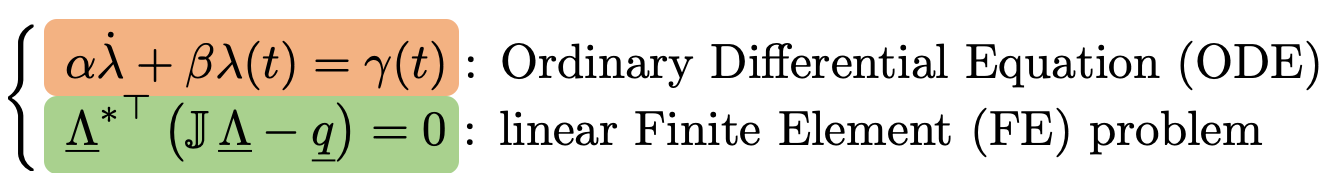

### **Here we go!**

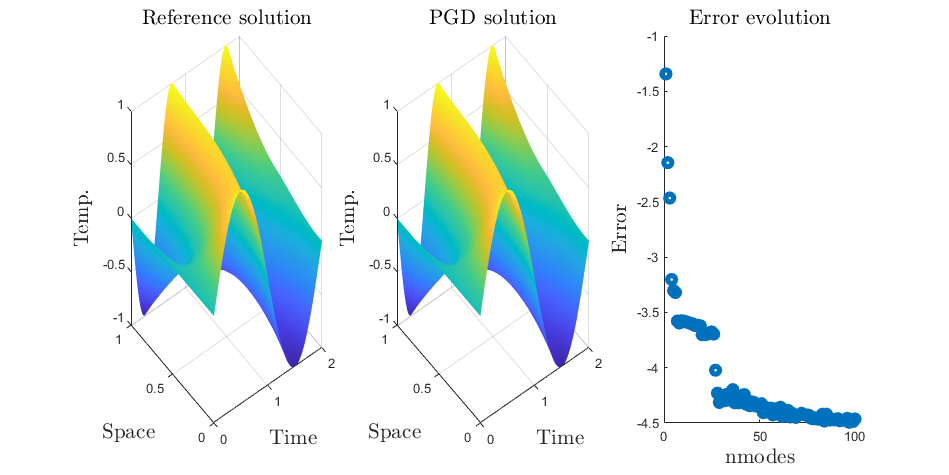

% TO DO!
for mode = 1:n_modes
    
    stagn=100;

    %%% TO DO : replace ones matrix with the good expressions

    %%% Fixed point
    Q= Q0 - M * W * Dt - K * W;

    % initialisation lambda
    lambdatmp = lt;

    niter=0;
    while stagn>valstagn && niter<10
        %%% Finite Element Problem
    
        % compute matrix and right-hand-side
        J= [lambdatmp * Dt * It * lambdatmp'] * M + [lambdatmp * It * lambdatmp'] * K;
        q= lambdatmp * It * Q';

        % Compute spatial mode
        LAMBDAtmp = zeros(n_X,1);
        LAMBDAtmp(ddlu) = J(ddlu,ddlu) \ q(ddlu)'; % only for free DOFs

         % Normalization of spatial mode
        LAMBDAtmp = LAMBDAtmp / sqrt(LAMBDAtmp' * Ix * LAMBDAtmp);

        % Store lambda from previous iteration
        lambdaold = lambdatmp;

        %%% Ordinary Differential Equation
        % Terms of the ODE
        alpha = LAMBDAtmp' * M * LAMBDAtmp;
        beta = LAMBDAtmp' * K * LAMBDAtmp;
        gamma = LAMBDAtmp' * Q;

        % Loop over time to solve the ODE
        for i = 2:n_T
            lambdatmp(i) = [gamma(i) + (alpha/dt) * lambdatmp(i-1)]/[(alpha/dt) + beta];
        end

        %%% Stagnation criterion
        stagn = ((lambdatmp-lambdaold)*It*(lambdatmp-lambdaold)')/(lambdaold*It*lambdaold');
        niter = niter+1;
        
    end
       
    %%% TO DO : store correctly the modes and compute W
    %%% Store new modes
    LAMBDA = [LAMBDA, LAMBDAtmp];
    lambda = [lambda; lambdatmp];
        
    %% Compute W
    W = LAMBDA * lambda;    

    % Compute hole PGD solution
    U_PGD = u_cl + W;

    %%% Error computation
    error = zeros(n_X, 1);
    norm_U_t = zeros(n_X, 1);
    for i = 1:n_X
        error(i) = sqrt((Uex(i,:) - U_PGD(i,:)) * It * (Uex(i,:) - U_PGD(i,:))');
        norm_U_t(i) = sqrt( Uex(i,:) * It * Uex(i,:)' );
    end
    pgd_err =  sqrt(error'*Ix*error)/sqrt(norm_U_t'*Ix*norm_U_t);
    pgd_errors = [pgd_errors,pgd_err];
     


    %%% Plot results
    figure(100)
    fig = gcf;
    fig.Position(3:4) = [2000, 1000];
    subplot(131)
    surf(lt,lx,Uex)
    shading interp
    xlabel('Time','Interpreter','latex','fontsize', 16)
    ylabel('Space','Interpreter','latex','fontsize', 16)
    zlabel('Temp.','Interpreter','latex','fontsize', 16)
    title('Reference solution','Interpreter','latex','fontsize', 16)
    shading interp

    subplot(132)
    surf(lt,lx,U_PGD)
    xlabel('Time','Interpreter','latex','fontsize', 16)
    ylabel('Space','Interpreter','latex','fontsize', 16)
    zlabel('Temp.','Interpreter','latex','fontsize', 16)
    title('PGD solution','Interpreter','latex','fontsize', 16)
    shading interp
    shading interp

    subplot(133) 
    %set(gca, 'YScale', 'log')
    %semilogy(pgd_errors ,'LineWidth',4)
    scatter(1:mode, log10(pgd_errors), 'LineWidth',4)
    xlim([0 n_modes])
    %ylim([1e-10 1e-1])
    xlabel('nmodes','Interpreter','latex','fontsize', 16)
    ylabel('Error','Interpreter','latex','fontsize', 16)
    title("Error evolution",'Interpreter','latex','fontsize', 16)

    % pause 
    % hold off
end
saveas(fig, sprintf('PGD_mode_%d.png', mode));

### To go further :

### 1) phase of updating temporal modes by Galerkin projection onto spatial modes (important)

### 2) comparison with an SVD decomposition of the reference solution

### 3) calculation of the theoretical complexity of the PGD and comparison with EF + Euler

## 1) PGD with phase of updating temporal modes by Galerkin projection onto spatial modes

### Initialization

% Initialization
Q0 = F - M * u_cl_dot - K * u_cl;
LAMBDA  = [];           % SPACE modes
lambda = [];            % TIME modes
W = zeros(n_X, n_T);   % PGD field
pgd_errors_update = [];

### Complete greedy PGD

for mode = 1:n_modes

    stagn = 100;

    %%% Fixed point
    Q = Q0 - M * W * Dt - K * W;
    lambdatmp = lt;

    
    niter = 0;
    while (stagn > valstagn) && (niter < 10)
        %%% Finite Element Problem
        % compute matrix and right-hand-side
        J = (lambdatmp * Dt * It * lambdatmp') * M + (lambdatmp * It * lambdatmp') * K;
        q = lambdatmp * It * Q';

        % Compute spatial mode
        LAMBDAtmp = zeros(n_X, 1);
        LAMBDAtmp(ddlu) = J(ddlu,ddlu) \ q(ddlu)';

        % Normalization of spatial mode
        LAMBDAtmp = LAMBDAtmp / sqrt(LAMBDAtmp' * Ix * LAMBDAtmp);

        % Store lambda from previous iteration
        lambdaold = lambdatmp;

        %%% Ordinary Differential Equation
        % Terms of the ODE
        alpha = LAMBDAtmp' * M * LAMBDAtmp;
        beta  = LAMBDAtmp' * K * LAMBDAtmp;
        gamma = LAMBDAtmp' * Q;

        % Loop over time to solve the ODE
        lambdatmp = zeros(1, n_T);
        for i = 2:n_T
            lambdatmp(i) = (gamma(i) + (alpha/dt)*lambdatmp(i-1)) / ((alpha/dt) + beta);
        end

        %%% Stagnation criterion
        stagn = ((lambdatmp - lambdaold)*It*(lambdatmp - lambdaold)') / (lambdaold*It*lambdaold');
        niter = niter + 1;
    end
    
    %%% Store new modes
    LAMBDA = [LAMBDA, LAMBDAtmp];
    lambda = [lambda; lambdatmp];


    %%% Gram-Schmidt process
    % Orthonormalisation
    for j = 1:(mode - 1)
        proj = LAMBDA(:, mode)' * Ix * LAMBDA(:, j);
        lambda(j, :) = lambda(j, :) + proj * lambda(mode, :);
        LAMBDA(:, mode) = LAMBDA(:, mode) - proj * LAMBDA(:, j);
    end
    
    % Normalisation
    norm_L = sqrt(LAMBDA(:, mode)' * Ix * LAMBDA(:, mode));
    lambda(mode, :) = lambda(mode, :) * norm_L;
    LAMBDA(:, mode) = LAMBDA(:, mode) / norm_L;


    %%% Update stage
    % Build the mode x mode matrices once (they don't change within the time loop)
    A_mat = zeros(mode, mode);
    M_mat = zeros(mode, mode);
    for p = 1:mode
        for r = 1:mode
            A_mat(p, r) = (1/dt) * LAMBDA(:,p)' * M * LAMBDA(:,r) ...
                         + LAMBDA(:,p)' * K * LAMBDA(:,r);
            M_mat(p, r) = (1/dt) * LAMBDA(:,p)' * M * LAMBDA(:,r);
        end
    end

    lambdaup = zeros(mode, n_T);
    % Loop over time
    for i = 2:n_T
        rhs = LAMBDA' * Q0(:,i) + M_mat * lambdaup(:, i-1);
        lambdaup(:, i) = A_mat \ rhs;
    end

    % Update variable lambda
    lambda = lambdaup';  % lambdaup is mode x n_T, lambda should be mode x n_T
    lambda = lambdaup;

    %%% Store correctly the modes and compute W
    W = LAMBDA * lambda;
    U_PGD_update = u_cl + W;

    %%% Error computation
    error_vec = zeros(n_X, 1);
    norm_U_t = zeros(n_X, 1);
    for i = 1:n_X
        error_vec(i) = sqrt((Uex(i,:) - U_PGD_update(i,:)) * It * (Uex(i,:) - U_PGD_update(i,:))');
        norm_U_t(i) = sqrt(Uex(i,:) * It * Uex(i,:)');
    end
    pgd_err = sqrt(error_vec' * Ix * error_vec) / sqrt(norm_U_t' * Ix * norm_U_t);
    pgd_errors_update = [pgd_errors_update, pgd_err];

    fprintf('Mode %d: error = %.6e (iter = %d)\n', mode, pgd_err, niter);

    %%% Plot results
    figure(200)
    fig = gcf;
    fig.Position(3:4) = [2000, 1000];
    subplot(131)
    surf(lt, lx, Uex)
    shading interp
    xlabel('Time','Interpreter','latex','fontsize', 16)
    ylabel('Space','Interpreter','latex','fontsize', 16)
    zlabel('Temperature','Interpreter','latex','fontsize', 16)
    title('Reference solution','Interpreter','latex','fontsize', 16)
    shading interp

    subplot(132)
    surf(lt, lx, U_PGD_update)
    xlabel('Time','Interpreter','latex','fontsize', 16)
    ylabel('Space','Interpreter','latex','fontsize', 16)
    zlabel('Temperature','Interpreter','latex','fontsize', 16)
    title('PGD solution with update phase','Interpreter','latex','fontsize', 16)
    shading interp
    shading interp

    subplot(133) 
    %set(gca, 'YScale', 'log')
    semilogy(pgd_errors_update,'LineWidth',4)
    xlim([0 n_modes])
    %ylim([1e-10 1e-1])
    xlabel('nmodes','Interpreter','latex','fontsize', 16)
    ylabel('Error','Interpreter','latex','fontsize', 16)
    title("Error evolution",'Interpreter','latex','fontsize', 16)
% 
    % pause 
    % hold off
end

Mode 1: error = 4.544367e-02 (iter = 3)
Mode 2: error = 6.557238e-03 (iter = 3)
Mode 3: error = 7.432850e-04 (iter = 3)
Mode 4: error = 1.882189e-04 (iter = 3)
Mode 5: error = 1.237437e-04 (iter = 6)
Mode 6: error = 9.579206e-05 (iter = 10)
Mode 7: error = 7.582655e-05 (iter = 10)
Mode 8: error = 6.545630e-05 (iter = 10)
Mode 9: error = 5.116809e-05 (iter = 10)
Mode 10: error = 4.629154e-05 (iter = 10)
Mode 11: error = 3.754297e-05 (iter = 10)
Mode 12: error = 3.317346e-05 (iter = 10)
Mode 13: error = 2.937562e-05 (iter = 10)
Mode 14: error = 2.604387e-05 (iter = 10)
Mode 15: error = 2.451980e-05 (iter = 10)
Mode 16: error = 2.204553e-05 (iter = 10)
Mode 17: error = 1.979961e-05 (iter = 10)
Mode 18: error = 1.774980e-05 (iter = 10)
Mode 19: error = 1.681230e-05 (iter = 10)
Mode 20: error = 1.593399e-05 (iter = 10)
Mode 21: error = 1.480720e-05 (iter = 10)
Mode 22: error = 1.379398e-05 (iter = 10)
Mode 23: error = 1.262691e-05 (iter = 10)
Mode 24: error = 1.194195e-05 (iter = 10)
Mode 2

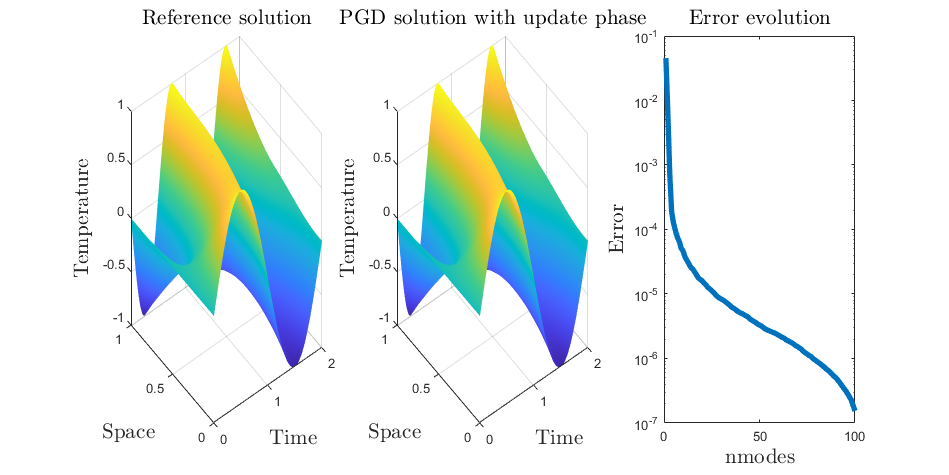

exportgraphics(fig, sprintf('PGD_update_mode_%d.png', mode), 'Resolution', 300);

### Comparison of PGD solutions with and without update

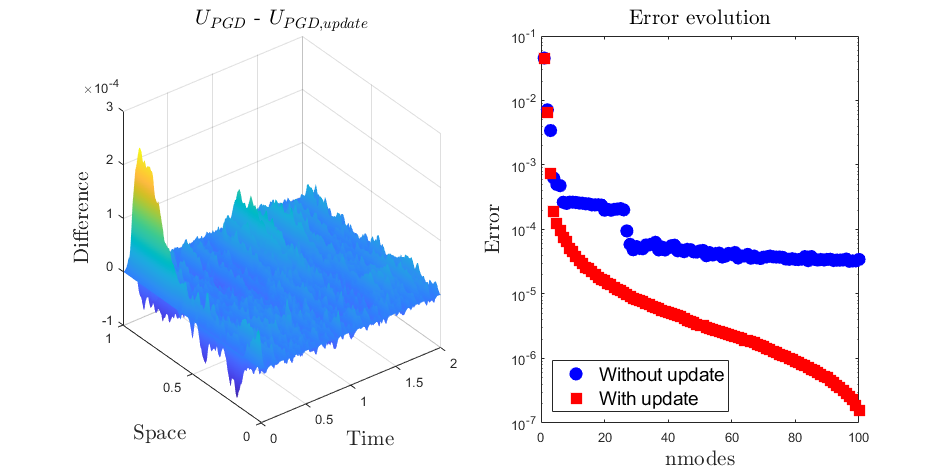

%% Comparison of PGD solutions with and without update
figure(300)
fig = gcf;
fig.Position(3:4) = [2000, 1000];

% Difference between both solutions
subplot(121)
surf(lt, lx, U_PGD - U_PGD_update)
shading interp
xlabel('Time','Interpreter','latex','fontsize', 16)
ylabel('Space','Interpreter','latex','fontsize', 16)
zlabel('Difference','Interpreter','latex','fontsize', 16)
title('$U_{PGD}$ - $U_{PGD,update}$','Interpreter','latex','fontsize', 16)
shading interp

% Plot convergence for both solutions
subplot(122)
semilogy(1:length(pgd_errors), pgd_errors, 'bo', 'LineWidth', 4, 'MarkerSize', 6, 'MarkerFaceColor', 'b')
hold on
semilogy(1:length(pgd_errors_update), pgd_errors_update, 'rs', 'LineWidth', 4, 'MarkerSize', 6, 'MarkerFaceColor', 'r')
hold off
xlim([0 n_modes])
xlabel('nmodes','Interpreter','latex','fontsize', 16)
ylabel('Error','Interpreter','latex','fontsize', 16)
title("Error evolution",'Interpreter','latex','fontsize', 16)
lgd = legend('Without update', 'With update');
lgd.FontSize = 14;
lgd.Location = 'southwest';
exportgraphics(fig, 'PGD_comparison.png', 'Resolution', 300);

## 2) Comparison with an SVD decomposition of the reference solution

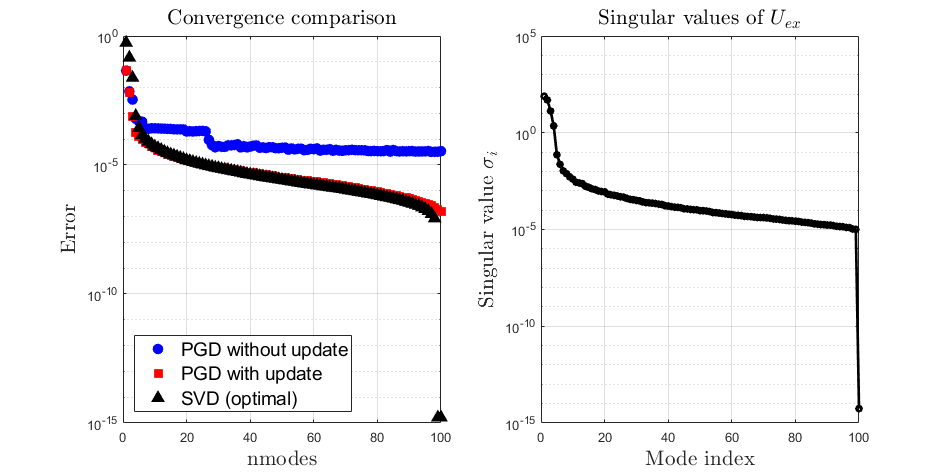

%% ========== Comparison with SVD decomposition ==========

% SVD of the reference solution
[U_svd, S_svd, V_svd] = svd(Uex, 'econ');

% Compute SVD errors for same number of modes as PGD
svd_errors = [];
for n = 1:n_modes
    Uex_svd = U_svd(:,1:n) * S_svd(1:n,1:n) * V_svd(:,1:n)';
    
    error_vec = zeros(n_X, 1);
    norm_U_t = zeros(n_X, 1);
    for i = 1:n_X
        error_vec(i) = sqrt((Uex(i,:) - Uex_svd(i,:)) * It * (Uex(i,:) - Uex_svd(i,:))');
        norm_U_t(i) = sqrt(Uex(i,:) * It * Uex(i,:)');
    end
    svd_err = sqrt(error_vec' * Ix * error_vec) / sqrt(norm_U_t' * Ix * norm_U_t);
    svd_errors = [svd_errors, svd_err];
end

% Plot: all three convergence curves
figure(400)
fig = gcf;
fig.Position(3:4) = [2000, 1000];

subplot(121)
semilogy(1:length(pgd_errors), pgd_errors, 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'b', 'LineWidth', 2)
hold on
semilogy(1:length(pgd_errors_update), pgd_errors_update, 'rs', 'MarkerSize', 6, 'MarkerFaceColor', 'r', 'LineWidth', 2)
semilogy(1:length(svd_errors), svd_errors, 'k^', 'MarkerSize', 6, 'MarkerFaceColor', 'k', 'LineWidth', 2)
hold off
xlim([0 n_modes])
xlabel('nmodes','Interpreter','latex','fontsize', 16)
ylabel('Error','Interpreter','latex','fontsize', 16)
title("Convergence comparison",'Interpreter','latex','fontsize', 16)
lgd = legend('PGD without update', 'PGD with update', 'SVD (optimal)');
lgd.FontSize = 14;
lgd.Location = 'southwest';
grid on

subplot(122)
semilogy(diag(S_svd(1:n_modes,1:n_modes)), 'k-o', 'LineWidth', 2, 'MarkerSize', 4)
xlabel('Mode index','Interpreter','latex','fontsize', 16)
ylabel('Singular value $\sigma_i$','Interpreter','latex','fontsize', 16)
title("Singular values of $U_{ex}$",'Interpreter','latex','fontsize', 16)
grid on
exportgraphics(fig, 'PGD_vs_SVD_comparison.png', 'Resolution', 300);

## 3) Calculation of the theoretical complexity of the PGD and comparison with EF + Euler

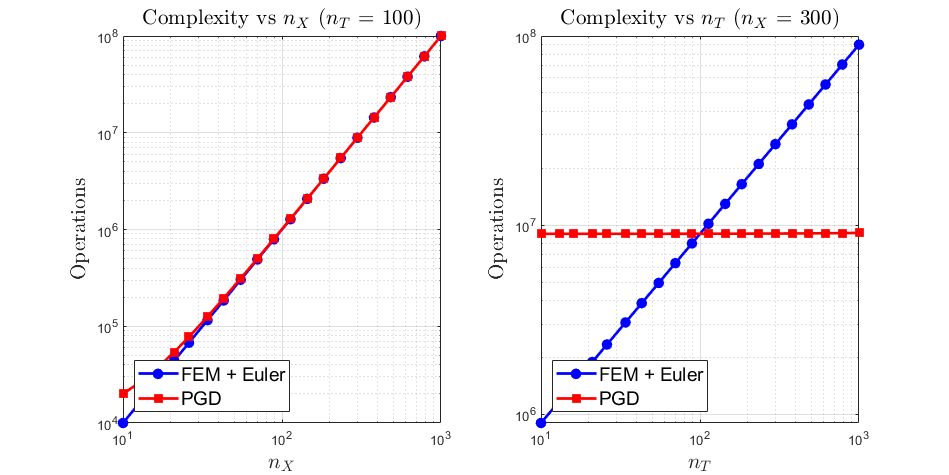

%% ========== Complexity comparison: PGD vs FEM+Euler ==========

% Parameters
nX_values = round(logspace(1, 3, 20));  % n_X from 10 to 1000
nT_values = round(logspace(1, 3, 20));  % n_T from 10 to 1000

% Fixed parameters for each sweep
n_T_fixed = 100;
n_X_fixed = 300;
n_iter_fp = 5;      % average fixed-point iterations per mode
n_m = 20;           % number of PGD modes needed

%% --- Sweep over n_X (fixed n_T) ---
cost_fem_nx = zeros(size(nX_values));
cost_pgd_nx = zeros(size(nX_values));

for idx = 1:length(nX_values)
    nx = nX_values(idx);
    nt = n_T_fixed;
    
    % FEM + Euler: n_T solves of n_X system (banded -> O(n_X) each)
    % Dense: O(n_T * n_X^2), Banded: O(n_T * n_X)
    cost_fem_nx(idx) = nt * nx^2;
    
    % PGD: n_m modes * n_iter_fp iterations * (FE solve O(n_X^2) + ODE solve O(n_T))
    cost_pgd_nx(idx) = n_m * n_iter_fp * (nx^2 + nt);
end

%% --- Sweep over n_T (fixed n_X) ---
cost_fem_nt = zeros(size(nT_values));
cost_pgd_nt = zeros(size(nT_values));

for idx = 1:length(nT_values)
    nx = n_X_fixed;
    nt = nT_values(idx);
    
    cost_fem_nt(idx) = nt * nx^2;
    cost_pgd_nt(idx) = n_m * n_iter_fp * (nx^2 + nt);
end

%% ========== Complexity comparison: PGD vs FEM+Euler ==========

figure(500)
clf
fig = gcf;
fig.Position(3:4) = [2000, 1000];

%% -----------------------------
% Complexity vs n_X
%% -----------------------------
subplot(121)

loglog(nX_values, cost_fem_nx, 'b-o', ...
    'MarkerSize', 6, ...
    'MarkerFaceColor', 'b', ...
    'LineWidth', 2)
hold on

loglog(nX_values, cost_pgd_nx, 'r-s', ...
    'MarkerSize', 6, ...
    'MarkerFaceColor', 'r', ...
    'LineWidth', 2)

hold off

xlabel('$n_X$','Interpreter','latex','fontsize',16)
ylabel('Operations','Interpreter','latex','fontsize',16)
title(['Complexity vs $n_X$ ($n_T$ = ' num2str(n_T_fixed) ')'], ...
    'Interpreter','latex','fontsize',16)

legend('FEM + Euler', 'PGD')
lgd = legend;
lgd.FontSize = 14;
lgd.Location = 'southwest';

grid on
xlim([min(nX_values) max(nX_values)])

%% -----------------------------
% Complexity vs n_T
%% -----------------------------
subplot(122)

loglog(nT_values, cost_fem_nt, 'b-o', ...
    'MarkerSize', 6, ...
    'MarkerFaceColor', 'b', ...
    'LineWidth', 2)
hold on

loglog(nT_values, cost_pgd_nt, 'r-s', ...
    'MarkerSize', 6, ...
    'MarkerFaceColor', 'r', ...
    'LineWidth', 2)

hold off

xlabel('$n_T$','Interpreter','latex','fontsize',16)
ylabel('Operations','Interpreter','latex','fontsize',16)
title(['Complexity vs $n_T$ ($n_X$ = ' num2str(n_X_fixed) ')'], ...
    'Interpreter','latex','fontsize',16)

legend('FEM + Euler', 'PGD')
lgd = legend;
lgd.FontSize = 14;
lgd.Location = 'southwest';

grid on
xlim([min(nT_values) max(nT_values)])

%% --- Export ---
exportgraphics(fig, 'PGD_complexity_comparison.png', 'Resolution', 300);